
SeatZ = importExampleData("example_data/example.txt");
accel = SeatZ.accel;
times = SeatZ.time;
times = times - times(1); % removing the start time to start at zero.
%times = seconds(times); % get it in seconds as a double


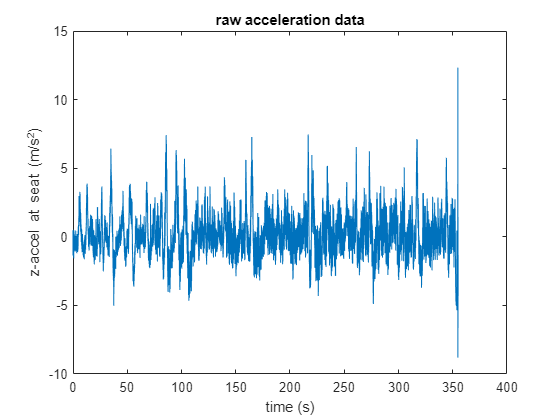

figure();
plot(times, accel);
ylabel("z-accel at seat (m/s^2)");
xlabel("time (s)");
title("raw acceleration data");

[thump_values, thump_times, impact_thump_values, impact_times, hatv, impact_bool_idx] = applyThumpMethod(accel, times);


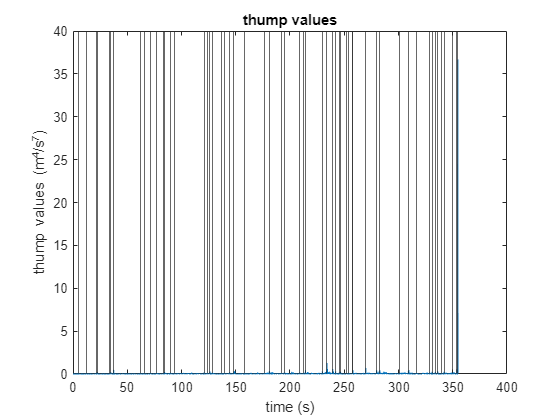

figure();
plot(thump_times, thump_values);
xline(impact_times);
ylabel("thump values (m^4/s^7)");
xlabel("time (s)");
title("thump values");

fprintf("Number of thump impacts: %d\n", sum(impact_bool_idx));

Number of thump impacts: 56


[womp_values, womp_times, jerk_comparison, jerk_impact_values, impact_bool_idx] = applyWompMethod(accel, times);

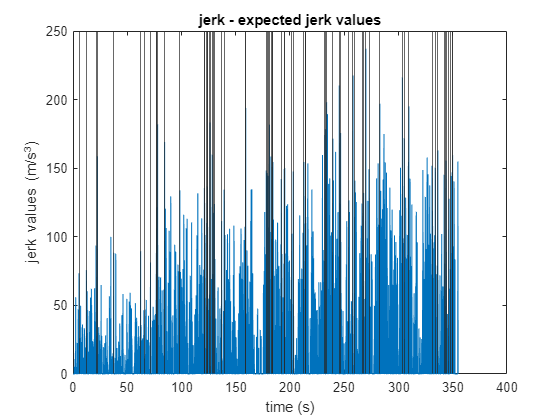

figure();
plot(times(2:length(times)), jerk_comparison);
xline(times(impact_bool_idx));
ylabel("jerk values (m/s^3)");
xlabel("time (s)");
title("jerk - expected jerk values");

fprintf("Number of womp impacts: %d\n", sum(impact_bool_idx));

Number of womp impacts: 70
